## **RT-QIBC analysis of cells treated with MLN-4924 (with siGeminin) **

**Variables:**

FarRed1 = mean EdU intensity within nucleus

POI_filter_time = PCNA foci time

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Conditions
conditions = {
         'siCTRL DMSO Cdt1',2,2:4,1:6,[0 0 0]; %1
         'siGMNN DMSO Cdt1',3,2:4,1:6,[0 0 0]; %1
         'siDTL  DMSO Cdt1',4,2:4,1:6,[0 0 0]; %1
         
         'siCTRL DMSO GMNN',2,5:6,1:6,[0 0 0]; %1
         'siGMNN DMSO GMNN',3,5:6,1:6,[0 0 0]; %1
         'siDTL  DMSO GMNN',4,5:6,1:6,[0 0 0]; %1
         
         'siCTRL MLN Cdt1',2,7:9,1:6,[0 0 0]; %1
         'siGMNN MLN Cdt1',3,7:9,1:6,[0 0 0]; %1
         'siDTL  MLN Cdt1',4,2:4,1:6,[0 0 0]; %1
         
         'siCTRL MLN GMNN',2,10:11,1:6,[0 0 0]; %1
         'siGMNN MLN GMNN',3,10:11,1:6,[0 0 0]; %1
         'siDTL  MLN GMNN',4,10:11,1:6,[0 0 0]; %1

};
% data = loadData(conditions, dataDir);
 data = load([dataDir 'C1037_data.mat'],'S');
 data = data.S;
[data.conditions] = deal(conditions);
[data.framesPerHr] = deal(60/10);
[data.numFrames] = deal(size(data(1).area,2));
[data.xFrames] = deal(1:data(1).numFrames);
[data.xTime] = deal((data(1).xFrames-1)./data(1).framesPerHr);
[data.experiment] = deal('C1037');
map = IXM_well_offset(conditions,6,1);
% POI_time = arrayfun(@(x) (x.numFrames - x.POI + repmat(cell2mat(map.values(x.shot)),1,size(x.POI,2)))/x.framesPerHr, data,'UniformOutput',false);
POI_time = arrayfun(@(x) (x.numFrames - x.POI)/x.framesPerHr, data,'UniformOutput',false);
% POI_filter_time = arrayfun(@(x) (x.numFrames - x.filterPOI + repmat(cell2mat(map.values(x.shot)),1,size(x.POI,2)))/x.framesPerHr, data,'UniformOutput',false);
POI_filter_time = arrayfun(@(x) (x.numFrames - x.filterPOI)/x.framesPerHr, data,'UniformOutput',false);

[data.POI_time] = POI_time{:};
[data.POI_filter_time] = POI_filter_time{:};

S = data;
clear data 

**Set thresholds**

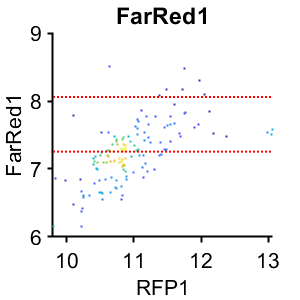

%% Set gates time after mitosis
cond=4;
gate = struct();
gates = {'FarRed1'};
plotting = {'RFP1'};
prctiles = {[50 95], [50 80],[50 95]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) <= 1.5 & S(cond).POI_time(:,1) > .5 &...
        isnan(S(cond).filterPOI(:,4)) & S(cond).FarRed1 < 2^9;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

%%%
conds=[1 2 7 8];
poiAligned=3;
range = (1/3:2/S(1).framesPerHr:3)-.00001;

f1= figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
cols = lines(2);
cols = cols([1 2 1 2],:);
lin = {'-','-',':',':'};
mean_out = [];
sem_out = [];
for i=1:length(conds)
   
    ind = true(size(S(conds(i)).area(:,1))) & S(conds(i)).POI_filter_time(:,poiAligned) <= 2.5;
    xdata=S(conds(i)).POI_filter_time(ind,poiAligned);
    ydata = [];
    ydata(:, 1) = (S(conds(i)).FarRed1(ind) - gate.FarRed1_G1(1)) ;
    
    ind = true(size(S(conds(i)+3).area(:,1)));
    xdata=[xdata; S(conds(i)+3).POI_filter_time(ind,poiAligned)];
    ydata_temp = [];
    ydata_temp(:, 1) = (S(conds(i)+3).FarRed1(ind)) ;
    ydata = [ydata; ydata_temp];

    edges = range;
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','std'},...
        'Edges',edges);
    midpoints = edges;
    midpoints = midpoints(1:end-1);
    
    fprintf("Cond %d, Min cells in bins: %d",i,min(binData(1).numCells(1:end-2)))
    fprintf("Cond %d, Total cells: %d",i,length(xdata))
    
    figure(f1), hold on
    errorbar(midpoints,binData(1).mean,2*binData(1).std./sqrt(binData(1).numCells),lin{i},'LineWidth',1.5,'Color',cols(i,:));
    ylim([0 6000]);
    xlim([0 2]);  
    ylabel('log2[EdU (RFU)]');xlabel('Time since PCNA foci (h)');
    axis square
end

Cond 1, Min cells in bins: 18

Cond 1, Total cells: 864

Cond 2, Min cells in bins: 11

Cond 2, Total cells: 793

Cond 3, Min cells in bins: 10

Cond 3, Total cells: 633

Cond 4, Min cells in bins: 8

Cond 4, Total cells: 613

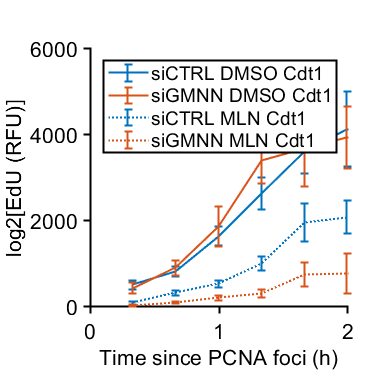


figure(f1)
legend(conditions(conds,1))
print_pdf([pwd() '\Figs\EdUMLNcompare_linear.pdf'])

## geminin vs APC for different conditions

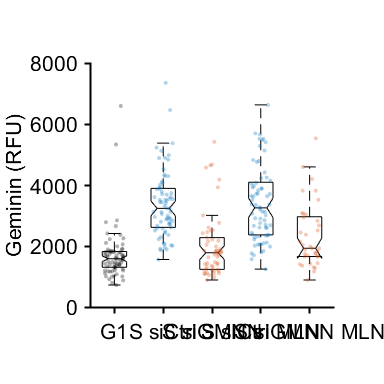

rng(1)

cond_g1 = 4;
cond_S = [4 5 10 11];
yval = 'RFP1';
ally = [];
group= [];
gind = 1;
%G1 
conds=cond_g1;

for i=1:length(conds)        
    condition=conds(i);
    %%G1 levels
    inds = S(conds(i)).POI_time(:,1) <= 2 & S(conds(i)).POI_time(:,1) > .5 &...
        isnan(S(conds(i)).POI_filter_time(:,3)) & S(conds(i)).FarRed1 < 2^7.5;
    ydata =  (S(condition).(yval)(inds));
    ydata = randsample(ydata, 73);
    ally = [ally; ydata];
    
    group = [group; gind*ones(size(ydata)) ];
    gind = gind + 1;
end

%S phase
conds=cond_S;
for i=1:length(conds)        
    condition=conds(i);
    %%Slevels
    inds =  S(conds(i)).POI_filter_time(:,3) >= 1 & S(conds(i)).POI_filter_time(:,3) <= 3  ;
    ydata =  (S(condition).(yval)(inds));
    ally = [ally; ydata];
    
    group = [group; gind*ones(size(ydata)) ];
    gind = gind + 1;
end

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
boxplot(ally,group,'Notch','on','Symbol','','Color','k');
hold on
groupcol = [[0 0 0];cols([1 2 1 2],:)];
jit = 0.4*rand(size(group))-.2;
scatter(group+jit, (ally), 10,groupcol(group,:),'filled','MarkerFaceAlpha',.3);
ylabel('Geminin (RFU)')
xticklabels({'G1','S siCtrl','S siGMNN','S siCtrl MLN','S siGMNN MLN'})
box off
axis square
ylim([0 8000])
print_pdf([pwd() '\Figs\gmnn_compare.pdf'])


num_cells = splitapply(@length,ally,group)

num_cells =     73
    70
    54
    73
    37
